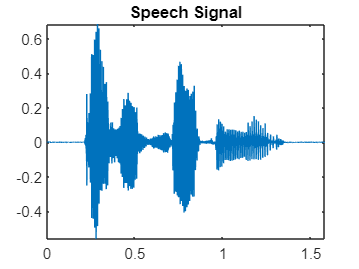

clc;
close all;
clear all;

[s0,Fs] = audioread('a0030.wav');
s = s0(:,1);
s1 = s0(:,2);

t = 1/Fs:1/Fs:size(s,1)/Fs;

plot(t,s);
title("Speech Signal");

% xlim([0.4 0.5]);


## Step 1

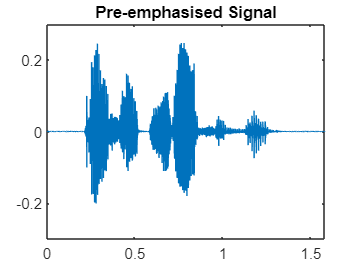


t1 = 1/Fs:1/Fs:(size(s,1)-1)/Fs;

sig_len = length(s);

x = [];

for i = 2:sig_len

    x = [x,s(i)-s(i-1)];

end

plot(t1,x);
title("Pre-emphasised Signal")

## Step 2

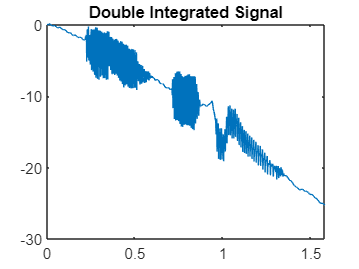


y1 = [0,0];

x_len = length(x);

for i = 3:x_len

    y1 = [y1,x(i)+2*y1(i-1)-y1(i-2)];

end

plot(t1,y1);
title("Double Integrated Signal");

## Step 3

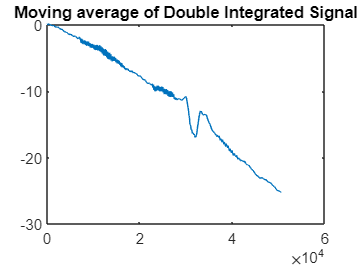


y = [];

filter_sig = smoothdata(y1,'movmean',320);

plot(filter_sig);
title("Moving average of Double Integrated Signal");

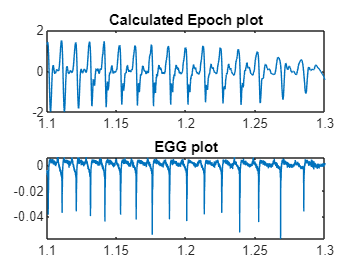


for i = 1:x_len

     y = [y,y1(i)-filter_sig(i)];

end

subplot(2,1,1)
plot(t1,y);
title("Calculated Epoch plot");
xlim([1.1 1.3]);
subplot(2,1,2)
plot(t1,diff(s1));
title("EGG plot");
xlim([1.1 1.3]);